# Model-Based Security Threat and Risk Analysis - Asset Identification

Threat analysis typically starts by identifying the *assets*. An asset is something valuable that needs protection. These are often safety-critical signals, secret encryption keys, data storage, and in general anything that is relevant in a safety context, since the loss of a safety feature is something that we want to avoid.

## Preparation

Security risk analysis mainly takes place in spreadsheets. [Click here](matlab:openSecurityAnalysis) to open all of them - we will come back to each of them in the upcoming steps.

Next, we need to make sure that the model is ready for security analysis. Towards this, [click here](matlab:tara.initialize) or run the following command:

tara.initialize

## Asset Identification

First, we need to decide what are our assets. [Click here](matlab:open('WareHouseTaskRobotArchitecture.slx')) to view the robot's internal architecture.

There are many methods to identify assets, for example, based on their exposure to a user, based on their data flows, based on an [SBOM](https://en.wikipedia.org/wiki/Software_supply_chain), or based on their role in safety features. As a simple rule of thumb, we at least must consider all components that are consuming external inputs. Hence, the following components must be treated as assets ([click here](matlab:open_system("WareHouseTaskRobotArchitecture")) to open the architecture first):

- Asset #1: [Position Estimator](matlab:hilite_system('WareHouseTaskRobotArchitecture/Position Estimator')), to make sure the robot is not crashing into anything, and

- Asset #2: [Planning Scheduler](matlab:hilite_system('WareHouseTaskRobotArchitecture/Planning Scheduler')), to make sure the robot is not executing any undesired commands.

*Note: Components with external inputs can be identified automatically with* [*Model Slicer*](https://mathworks.com/help/slcheck/ug/identify-model-interest-to-isolate-dependencies.html) *or with* [*Spotlight Views*](https://uk.mathworks.com/help/systemcomposer/ug/create-spotlight-views.html)*.*

The assets are captured in the [assets spreadsheet](matlab:open('assets.mldatx')). Each row in the sheet describes one asset, with columns capturing its properties. You should see one pre-existing row for the asset "Planning Scheduler":

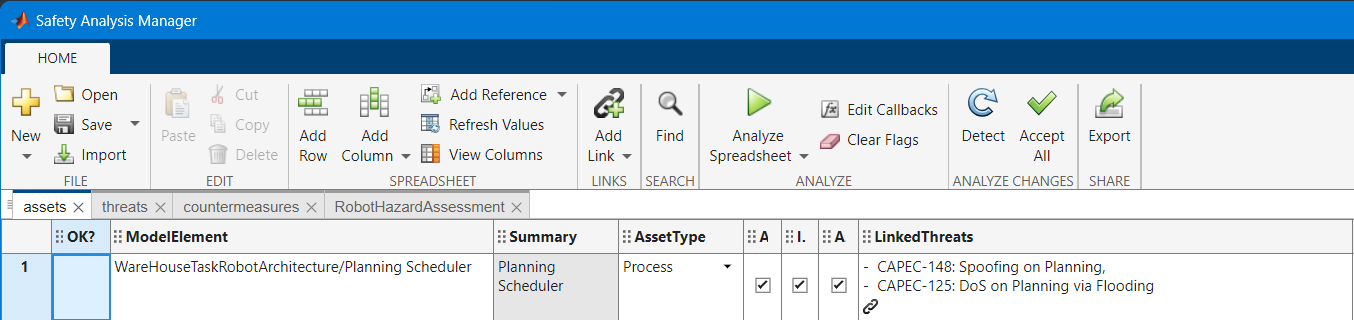

Next, we will show how to add the [Position Estimator](matlab:hilite_system('WareHouseTaskRobotArchitecture/Position Estimator')) to the assets sheet.

## Automatic Asset Scan

To declare the [Position Estimator](matlab:hilite_system('WareHouseTaskRobotArchitecture/Position Estimator')) as an asset, first select the component in the model, then add the stereotype "securityAsset" via the context menu **Apply Stereotype > securityProfile.securityAsset**:

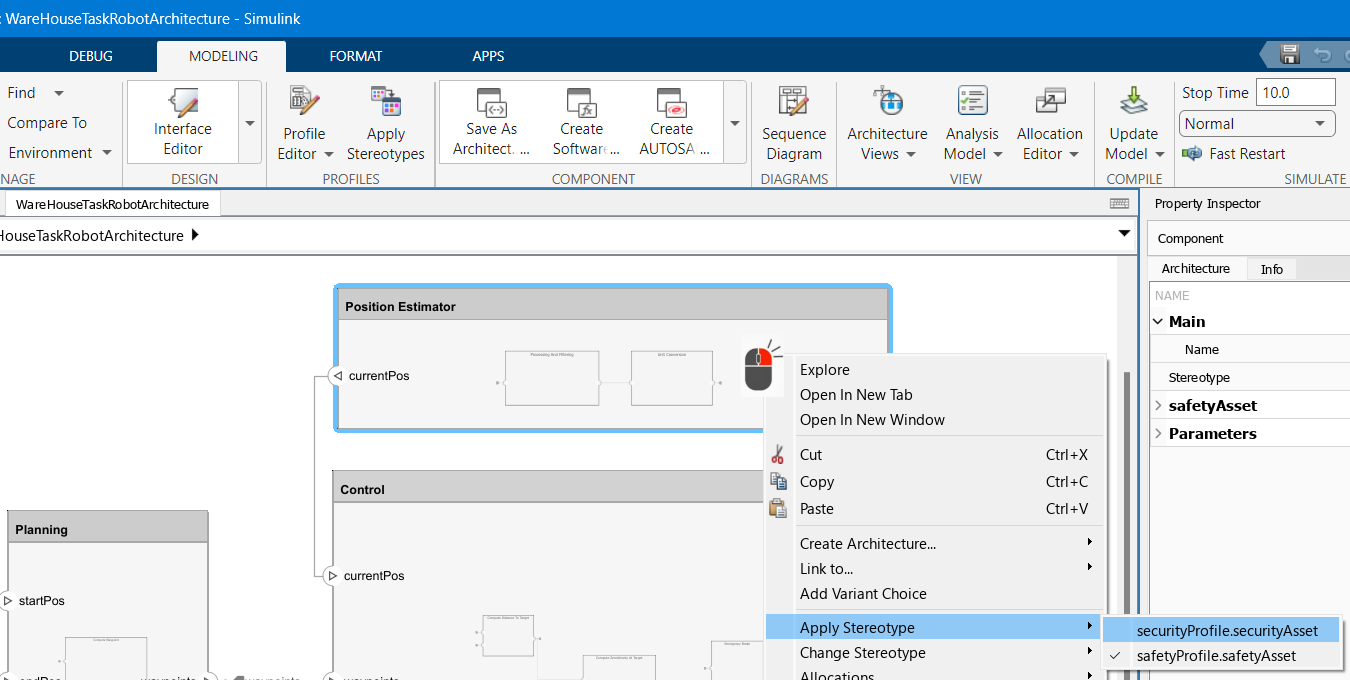

Next, go back to the [assets sheet](matlab:open('assets.mldatx')), to run an analysis function that automatically collects the new asset as follows: 

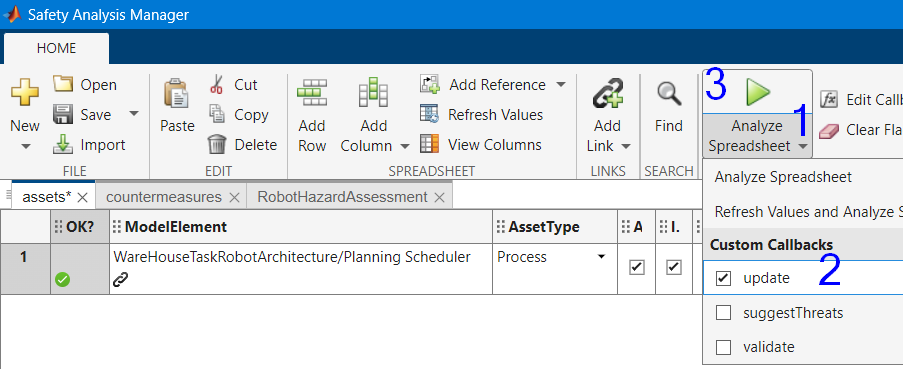

- Open the dropdown menu (1) on the **Analyze Spreadsheet** button,

- then enable the *update* function (2),

- finally click the **Analyze Spreadsheet** button (3).

After the update, one new row has been added to the assets sheet, representing the "Position Estimator":

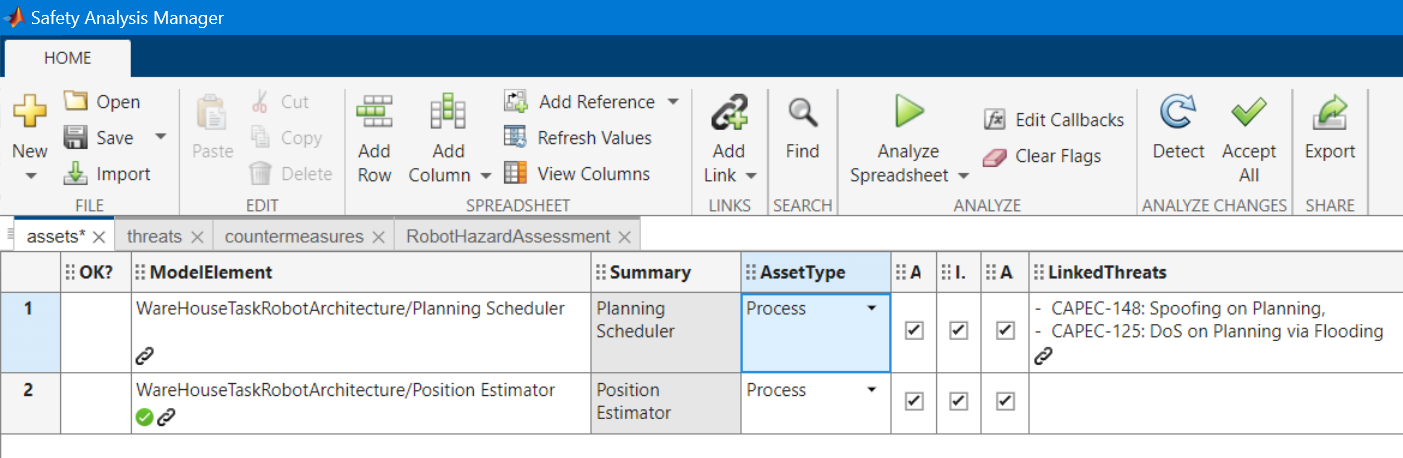

Note the little chain icon in the column **ModelElement**. This is a bidirectional link between your model and your asset sheet. It provides traceability in both directions, and ensures that risk data remains in sync with your architecture.

To navigate back from the model to the spreadsheet, switch to the **Requirements Perspective** (1 or [click here](matlab:slreq.openRequirementsManager('WareHouseTaskRobotArchitecture'))), then use the document icon on the top right corner (2) of the component, and finally click the link (3):

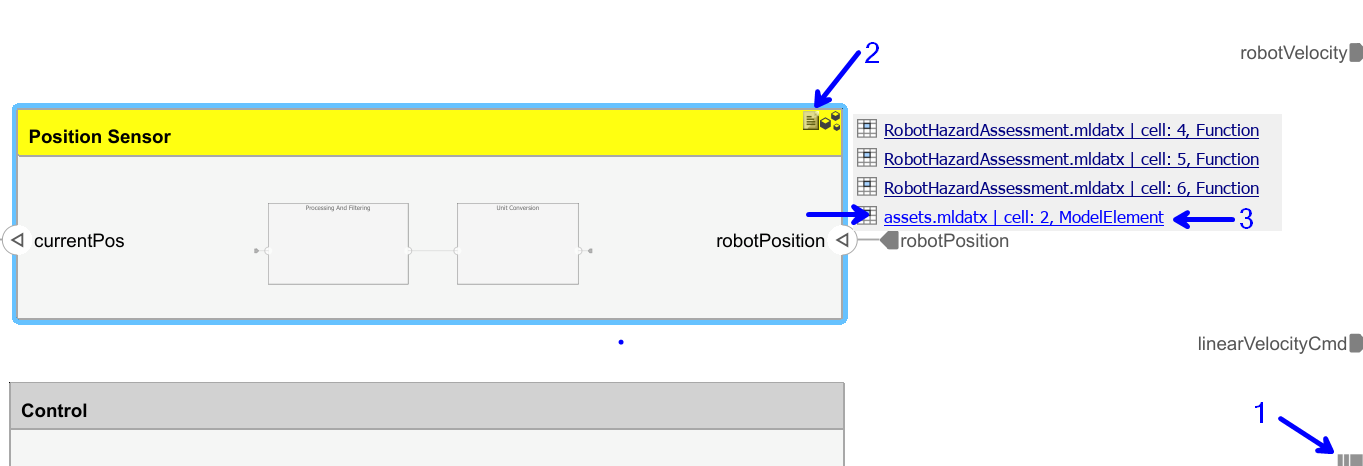

## Cybersecurity Properties

Each asset has one or more cybersecurity properties that we are trying to protect. Typically, there are six properties but to keep it simple, we only focus on three in this tutorial:

- Availability - system is accessible and operational

- Integrity - data/behavior is accurate and consistent

- Authenticity - component, message, or transaction is genuine

These properties can be seen as checkboxes in the assets sheet. They are automatically suggested when an asset is added, based on the type of architectural element it refers to. A manual review and refinement is advisable, to minimize the work later on. In our example, the new asset has been marked with all three properties.

## Final Result and Validation

You should now have two rows in your [assets sheet](matlab:open('assets.mldatx')). To ensure nothing is missing, run the *validate* function on the sheet by doing the following

- Open the dropdown menu on the **Analyze Spreadsheet** button,

- then enable the *validate* function,

- finally click the **Analyze Spreadsheet** button.

The result should be as shown below:

 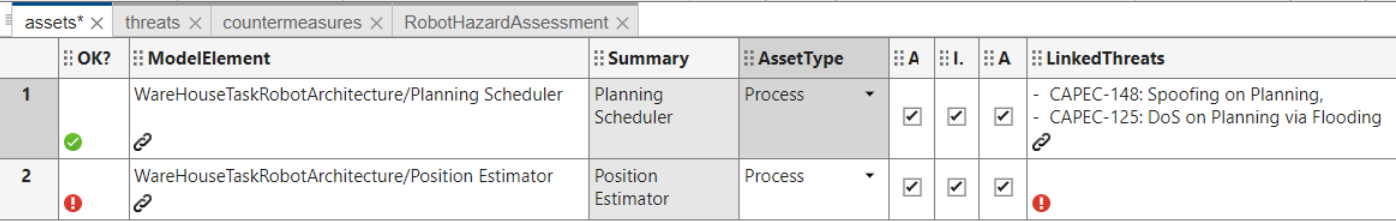

The column "**OK?**" is important - it shows where more work is needed:

- A green checkmark indicates that an asset is fully captured and processed.

- A red exclamation mark indicates that more steps are required. 

In our example, the asset "Planning Scheduler" is already complete and should be shown with a green checkmark. However, the newly captured asset "Position Estimator" has a red exclamation mark - this is because we have not yet defined threats to this asset.

## What's next?

Before you go to next steps [click here](matlab:saveAll()) to save all artifacts.

Continue with the next step - [threat identification](matlab:open('Tutorial_Step02_Threat')) or go back to the [overview page](matlab:open('Tutorial')).